% ----------------------------------------------
% Accountant under compositions
% last updated: 06/10/2022
% ----------------------------------------------
% First, we obtaining discrete distribution pair (po,qo)
% The method used here are: 
% Advanced Fourier Accountant, Moments Accountant.
% ----------------------------------------------

clear
close all

% let the show begin!
% note that for a single composition, we can compute the Egamma directly.

composition = 100;

comp_list=[1,100,200,300,400,500,1000,2000,3000,4000,5000];
sen = 1;
subsampling = 0.1;
sigma=sqrt(1);
noise_type=0;

switch noise_type
    case 0
        load(sprintf("cactus_s%.1f_L2=%.2f.mat",sen,sigma^2))
        x_grid=x(1:end-sen*n);
        x_max=max(x_grid);
        po=p(1:end-sen*n);
        qo= subsampling*p(sen*n+1:end)+(1-subsampling)*po;
    otherwise
        % guassian
        if noise_type==1
            f = @(x) 1/sqrt(2*pi)/sigma*exp(-1/2*x.^2/sigma^2);

            pq = @(x)1./(1-subsampling+subsampling.*exp(-1/2/sigma^2*(2*x+1)));
        else
            % laplace
            b=sigma/sqrt(2);
            f = @(x) 1/2/b*exp(-abs(x)/b);
        end
        % Take samples, and its shift/subsampled.
        x_max = sigma*7;
        x_step_size = 1e-4;
        n = 1/x_step_size;
        x_grid = -x_max:x_step_size:x_max;
        po = f(x_grid)*x_step_size;
        qo = subsampling*f(x_grid+sen)*x_step_size+(1-subsampling)*po;
        po=po';
        qo=qo';

        pq_list=pq(x_grid)';

end

Error using load
Unable to find file or directory 'cactus_s1.0_L2=1.00.mat'.


% this right here is a hack! This code is not properly accounting for the tails of the distribution
% po = po/(sum(po));
% qo = qo/(sum(qo));

KL=sum(po.*log(po./qo));

figure
subplot(1,2,1);
plot(x_grid,po,"LineWidth",2,'DisplayName','p(x)')
hold on
plot(x_grid,qo,"LineWidth",2,'DisplayName','q(x)')
xlabel('x','FontSize',15)
ylabel('pdf','FontSize',15)
title('pdf','FontSize',15)
legend;
grid on

subplot(1,2,2);
plot(x_grid,log(po./qo),'.',"LineWidth",2)
xlabel('x','FontSize',15)
ylabel('log(po/qo)','FontSize',15)
title('log(po(x)/qo(x))','FontSize',15)
grid on

Eg=@(gamma) sum(max(0,po-gamma*qo));
% Eg=@(gamma) sum(x_step_size*po.*max(0,1-gamma./pq_list));
% Eg = @(gamma) 1/2*(erfc((-1+2*sigma^2*log(gamma))/2/sqrt(2)/sigma)-...
%     gamma*erfc((1+2*sigma^2*log(gamma))/2/sqrt(2)/sigma));


% Next, we sample the Egamma curve uniformly.
if noise_type==1
    
    if subsampling~=1
        rate=po./qo;
        gamma_max=max(rate);
        gamma_min=min(rate);
    else
        gamma_max=min(10,exp(composition*KL*5));
    end
else
    rate=po./qo;
%     gamma_max=max(rate(1:end-n*sen));
    gamma_max=max(rate);
    gamma_min=min(rate);
end

l_step_size=(log(gamma_max)-log(gamma_min))/n/2;
l_grid=log(gamma_min):l_step_size:log(gamma_max);


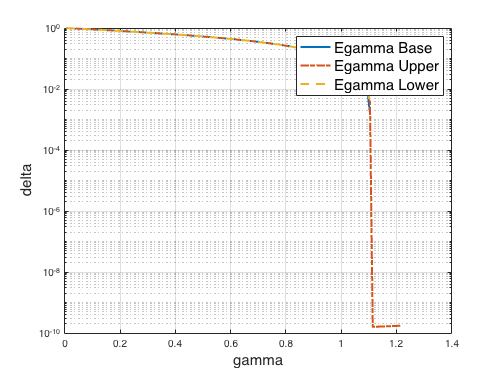

% ----------------------------------------------
% Advanced Fourier Accountant:
% ----------------------------------------------
% Step 1: Obtain a E-gamma curve on gamma_grid via function Eg(gamma_grid) -> Eg_grid
%
% Step 2(a): Obtain distribution pair upper bounding Eg_grid -> (p2,q2)
%       (b): Use (eps_grid,p2) as a random variable L_low 
%       (c): Perform FFT and iFFT to get convoluted (l_grid_padding,fLConvFFT_array2)
%       (d): Compute the Egamma_upper()
%
% Step 3(a): Obtain distribution pair lower bounding Eg_grid -> (p3,q3)
%       (b): Use (eps_grid,p3) as a random variable L_low 
%       (c): Perform FFT and iFFT to get convoluted (l_grid_padding,fLConvFFT_array3)
%       (d): Compute the Egamma_lower()
% ----------------------------------------------

% Now, we sample uniformly on epsilon = log(gamma)
% Few things to note:
% (1) For gamma starts from 0, epsilon starts from some negetive value.
% (2) Since the sample is even on log(gamma), we also need dynamic step
% size on gamma. As the samples are dense on the left and loose on the
% right.

gamma_grid2 = exp(l_grid); % convert it to gamma, now the gamma samples are uniform on log

% Again, we use Egamma2 for verifing the result, it should be an upper bound of the true Egamma curve.
[p2,q2] = pq_upper(Eg,gamma_grid2);

% Lastly, we get a lower bounding discrete model (p3,q3).
Egslope = @(gamma) -sum(qo(po>gamma*qo));
[p3,q3] = pq_lower(Eg,Egslope,gamma_grid2);


figure
gamma_test2 = gamma_min:1e-2:gamma_max*1.1;
semilogy(gamma_test2,arrayfun(Eg,gamma_test2),...
    "LineWidth",2,"DisplayName","Egamma Base");
hold on

Egamma_upper = @(gamma) sum(max(0,p2-gamma*q2));
Eg_array_upper2 = arrayfun(Egamma_upper,gamma_test2);
semilogy(gamma_test2,Eg_array_upper2,'-.',...
    "LineWidth",2,'DisplayName','Egamma Upper');
hold on

Egamma_lower = @(gamma) sum(max(0,p3-gamma*q3));
Eg_array_lower = arrayfun(Egamma_lower,gamma_test2);
semilogy(gamma_test2,Eg_array_lower,'--',...
    "LineWidth",2,'DisplayName','Egamma Lower');

xlabel("gamma",'FontSize',15);
ylabel("delta",'FontSize',15);
legend('FontSize',15)
grid on

% We are ready to perform FFT to obtain the convoluted pdf. 

% First, we set the delta value
delta=1e-10;


% Step 2 - FFT Upper

% There's a minor problem with the upper bounding model, since the last value has q2(end)=0 but
% p2(end)>0. This correspondings to an infinite value of L, which doesn't show up in the grid.
% We can deal with this by slicing off the last value, then adding back to delta the probability 
% that any of the compositions happens to hit the last value. This occurs with probability
% 1-(1-p2(end))^composition
% [l_grid_padding,fLConvFFT_array2] = fft_ConvN(l_grid,p2(2:end-1),composition);
% delta_FFT_upper_bd = @(eps) sum(fLConvFFT_array2.*max(0,1-exp(eps-l_grid_padding)))+(1-(1-p2(end))^composition);


delta_FFT_upper_array=zeros(1,length(comp_list));
for i=1:length(comp_list)
    [l_grid_padding,fLConvFFT_array2] = fft_ConvN(l_grid,p2(2:end-1),comp_list(i));
    delta_FFT_upper = @(eps)sum(fLConvFFT_array2.*max(0,1-exp(eps-l_grid_padding)))-delta;
    delta_FFT_upper_array(i)=fzero(@(eps) delta_FFT_upper(eps),comp_list(i)*KL);      
end


% Step 3 - FFT Lower

% We can actually avoid all FFT shifting (and normalization) if we zero-pad at the end of 
% the vector, rather than on both sides. In fact the fft function will automatically do this
% if we just add a second argument with the desired length
% [l_grid_padding,fLConvFFT_array3] = fft_ConvN(l_grid,p3,composition);
% delta_FFT_lower_bd = @(eps) sum(fLConvFFT_array3.*max(0,1-exp(eps-l_grid_padding)));

delta_FFT_lower_array=zeros(1,length(comp_list));
for i=1:length(comp_list)
    [l_grid_padding,fLConvFFT_array3] = fft_ConvN(l_grid,p3,comp_list(i));
    delta_FFT_lower= @(eps)sum(fLConvFFT_array3.*max(0,1-exp(eps-l_grid_padding)))-delta;
    delta_FFT_lower_array(i)=fzero(@(eps) delta_FFT_lower(eps),0);
end

% Step Bonus - Moments accountant

alpha_max = 60; %maximum lambda in MGF
alpha_grid =1.1:0.1:alpha_max;
rdp = ma_ComputeRDP(po,qo,alpha_grid);
delta_MA_array=zeros(1,length(comp_list));
for i=1:length(comp_list)
    delta_MA = @(eps)ma_ComputeDelta(alpha_grid, comp_list(i)*rdp,eps)-delta;
    delta_MA_array(i)=fzero(@(eps) delta_MA(eps),comp_list(i)*KL);
end

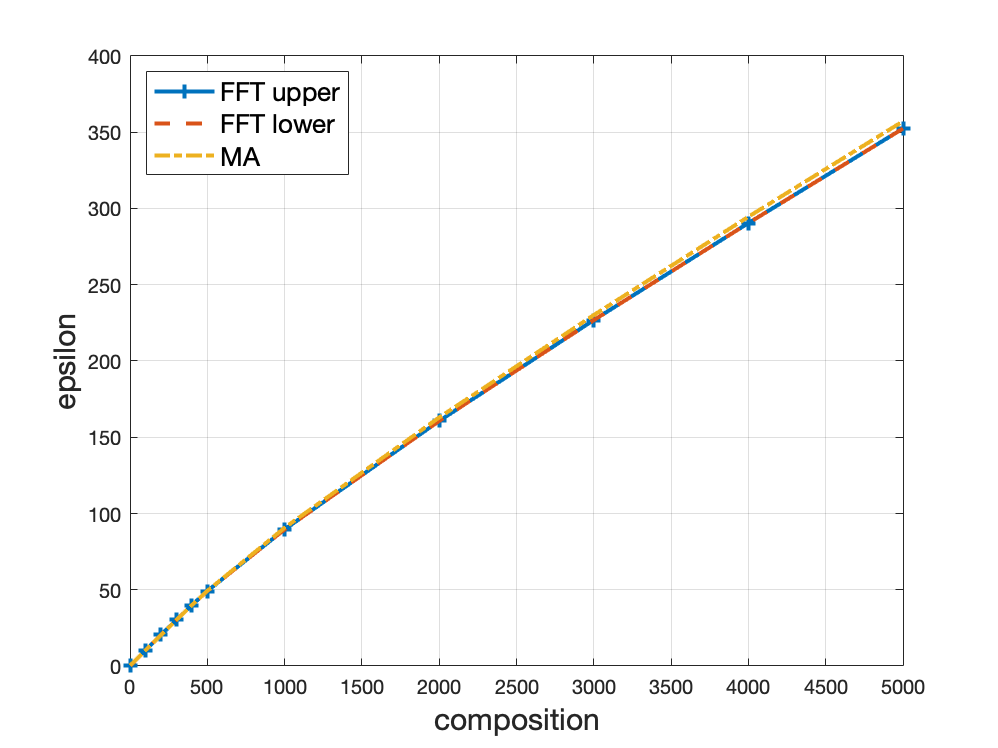

% We save the epsilon values respect to comp_list
noise_name=["cactus" "gaussian"];
filename = sprintf('delta_composition_%s.mat',noise_name(noise_type+1));
save(filename,'comp_list','delta_FFT_upper_array','delta_FFT_lower_array','delta_MA_array');

figure

plot(comp_list,delta_FFT_upper_array,'-+',...
    'LineWidth',2,'DisplayName','FFT upper');
hold on

plot(comp_list,delta_FFT_lower_array,'--',...
    'LineWidth',2,'DisplayName','FFT lower');
hold on

plot(comp_list,delta_MA_array,'-.',...
    'LineWidth',2,'DisplayName','MA');
hold off

legend("FontSize",13,"Location",'northwest');
xlabel('composition','FontSize',15)
ylabel('epsilon','FontSize',15)
grid on


% The whole idea here is the following: we first derive the approximate
% (P,Q) pair which has the same E-gamma curve but also has nice bijictive
% properties that leads to the (approximate) privacy loss random variable,
% then we are ready to apply the FFT to compute the convoluted pdf to deal
% with compositions.

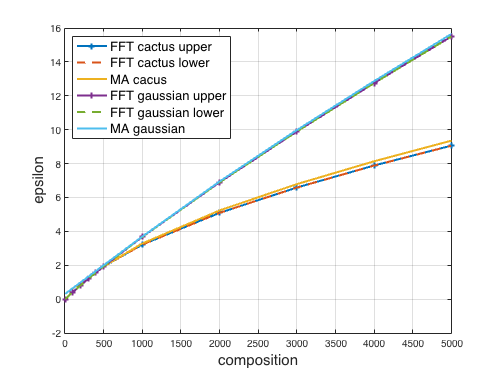

figure

load("delta_composition_cactus.mat")

plot(comp_list,delta_FFT_upper_array,'-+',...
    'LineWidth',2,'DisplayName','FFT cactus upper');
hold on

plot(comp_list,delta_FFT_lower_array,'--',...
    'LineWidth',2,'DisplayName','FFT cactus lower');
hold on

plot(comp_list,delta_MA_array,'-',...
    'LineWidth',2,'DisplayName','MA cacus');
hold on 


load("delta_composition_gaussian.mat")

plot(comp_list,delta_FFT_upper_array,'-+',...
    'LineWidth',2,'DisplayName','FFT gaussian upper');
hold on

plot(comp_list,delta_FFT_lower_array,'--',...
    'LineWidth',2,'DisplayName','FFT gaussian lower');
hold on

plot(comp_list,delta_MA_array,'-',...
    'LineWidth',2,'DisplayName','MA gaussian');
hold off 

legend("FontSize",13,"Location",'northwest');
xlabel('composition','FontSize',15)
ylabel('epsilon','FontSize',15)
grid on